# Practical 6

## Question Form

Phtalic Anhydride (PA) Used in theproductionof C4 ÷C10alcohol phthalates, whichare used as plasticizers of PVC (e.g.: estherification of PAwith 2-ethylhexanol), by converting hard and brittle thermoplastics intomore flexible and elastic materials. In thecaseof PVCfor pipingand films, 30÷70%w/wof plasticizersare addedtosubstantiallymodifytheproperties. 

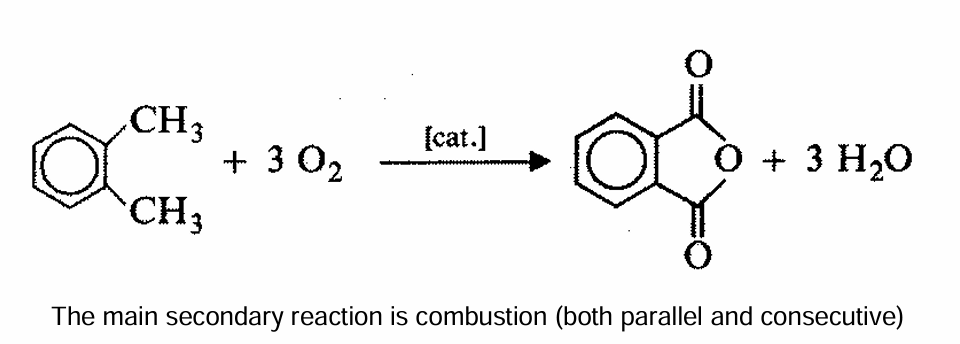

The reaction mechanism is described as follows:


$$\begin{array}{l}
C_6 H_4 {\left({\textrm{CH}}_3 \right)}_2 +3O_2 \to C_6 H_4 {\left(\textrm{CO}\right)}_2 O+3H_2 O\;\;\left(1\right)\;\;\;\;\;\;\;\;\Delta H=-1285409\;\frac{\textrm{kJ}}{\textrm{kmol}}\\
C_6 H_4 {\left({\textrm{CH}}_3 \right)}_2 +10\ldotp 5O_2 \to 8{\textrm{CO}}_2 +5H_2 O\;\;\;\;\;\left(2\right)\;\;\;\;\;\;\;\;\;\;\;\;\Delta H=-4564000\;\frac{\textrm{kJ}}{\textrm{kmol}}\\
C_6 H_4 {\left(\textrm{CO}\right)}_2 O++7\ldotp 5O_2 \to 8{\textrm{CO}}_2 +2H_2 O\;\;\;\;\left(3\right)\;\;\;\;\;\;\;\;\;\;\Delta H=-327859\;\frac{\textrm{kJ}}{\textrm{kmol}}
\end{array}$$


The process diagram is shown in the figure below:

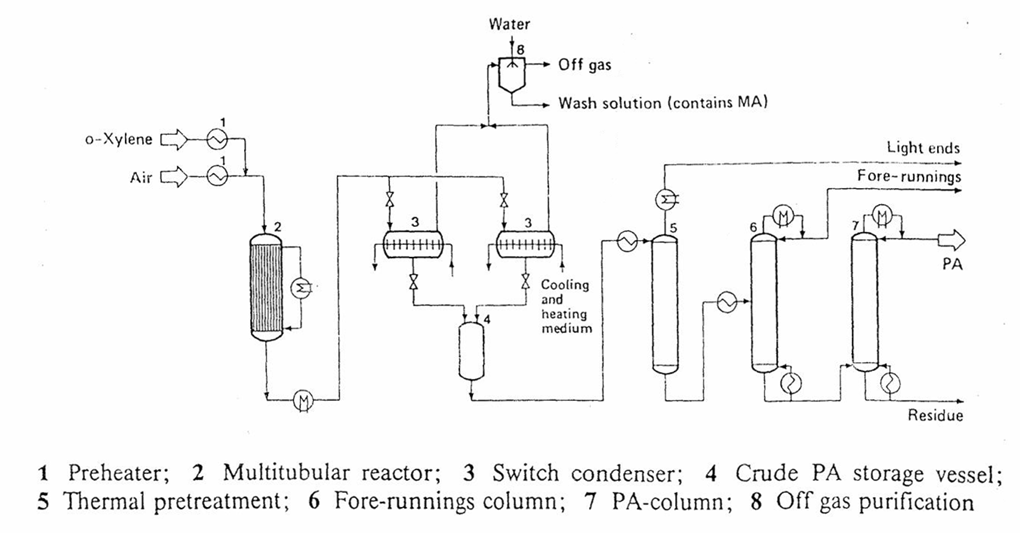

**Reactors**: multi-tubular fixed bed, cooled by circulation of molten salts  (e.g.  eutectic ${\textrm{KNO}}_3$:${\textrm{NaNO}}_3$ 57:43), in turn used to produce high pressure steam; thousandsof tubes with a diameter of 1“and length 3 mareused!

Design a multi-tubular reactor with capacity 8000 ton/yr of Phthalic anhydride, and determine this factors:

- Number of Tubes?

- Tube Diameter?

- Tube Length?

The operating conditions are as follows:

- Maximum allowable pressure drop: 0.1 bar/m

-  Temperature: 330 – 415°C

-  Pressure: 100-200 kPa

- Diluted conditions: o-xylene to air ratio (v/v) 1-2%

-  Catalytic particles: equivalent diameter of a sphere d = 5 mm – catalyst  density 2100 kg/m3

 Reaction rates are first order with respect to the reactants (Froment & Bishoff):


$$r=k\ldotp p_A \ldotp p_B$$


and kinetics constants are expressed as follows:


$$\begin{array}{l}
\ln \left(k_1 \right)=19\ldotp 837-\frac{13636}{T}\\
\ln \left(k_2 \right)=18\ldotp 970-\frac{14394}{T}\\
\ln \left(k_3 \right)=20\ldotp 860-\frac{15803}{T}
\end{array}$$


*** r in [kmol/kgcat/h], pressure in [bar] and T in [K].***

Each tube is equivalent in terms of conditions: single-tube model 

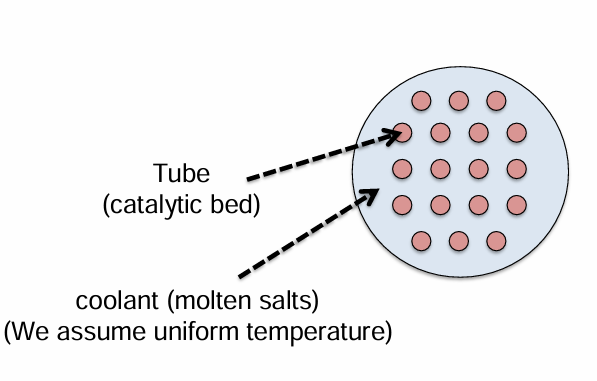

The void fraction of each tube is expressed in the following equation:


$$\varepsilon =0\ldotp 363+0\ldotp 35\;\exp \left(-0\ldotp 39\;\frac{d_{\mathrm{tube}} }{d_{\mathrm{sphere}} }\right)$$


## Assumptions

-  The basic model assumes that concentration and temperature gradients only occur in the axial direction.

- By assumption there is no concentration/temperature  difference between the catalyst and the bulk of the gas-phase.

- The only transport mechanism operating in this direction is the  overall flow itself (plug-flow). 

-  Specific heat of the mixture and viscosity can be considered constant

## 1D psuodo homogeneous model 

### Mass Balance


$$\begin{array}{l}
-G\;\frac{{d\omega }_i }{\textrm{dz}}+\sum_{j=1}^{\textrm{NR}} \nu_{i,j} r_j \left(1-\varepsilon \right)\rho_{\textrm{cat}} {\textrm{MW}}_i =0\\
B\ldotp C:\textrm{@z}=0\Rightarrow \omega_i =\omega_i^0 \\
G=\frac{\dot{m} }{A}
\end{array}$$


### Energy Balance


$$\begin{array}{l}
-G\hat{C_P } \;\frac{\textrm{dT}}{\textrm{dz}}-\sum_{j=1}^{\textrm{NR}} \Delta \tilde{H_{r,j} r_j \left(1-\varepsilon \right)\rho_{\textrm{cat}} +\frac{4}{d_{\textrm{tube}} }U\left(T_{\textrm{ext}} -T\right)=0} \\
B\ldotp C:\textrm{@z}=0\Rightarrow T=T_0 
\end{array}$$


### Pressure Balance (Ergun Equation)


$$\begin{array}{l}
-\frac{\textrm{dP}}{\textrm{dz}}+150\;\frac{{\left(1-\varepsilon \right)}^2 }{\varepsilon^3 }\;\frac{\mu v_s }{d_p^2 }+1\ldotp 75\;\frac{\left(1-\varepsilon \right)}{\varepsilon^3 }\;\frac{\rho v_s^2 }{d_p }=0\\
B\ldotp C:\textrm{@z}=0\Rightarrow P=P_0 
\end{array}$$


## Parameters and Initialization

close all  clear  clc
global Stoichiometry deltaH mw SpecificHeatP Viscosity ...
    TubeDiameter CatalystDensity U ...
    VoidFraction MoltenSaltsTemperature G ParticleDiameter NS NR 
%Reaction :
            % N2 O2 C6H4(CH3)2 C6H4(CO)2O H2O CO2
Stoichiometry=[0 -3 -1 1 +3 0
               0 -10.5 -1 0 5 8
               0 -7.5 0 -1 2 8];
deltaH=[-1285409 -4564000 -3278591]; %kJ/kmol

%Species:
mw=[28 32 106.16 148.12 18 44]; %kg/kmol
SpecificHeatP=0.992; %kJ/kg/K
Viscosity=2.95e-5; %Pa*s
NS = 6;
NR = 3;

% Reactor:
TubeDiameter=0.0254; %m
ParticleDiameter=0.005; %m
ReactorLength=3; %m
CatalystDensity=2100; %kg/m3
DiameterRatio=TubeDiameter/ParticleDiameter;
VoidFraction=0.363+0.35*(exp(-0.39*DiameterRatio));
U = 385.28; % kJ/m2/h/K

% Operating Conditions:
MoltenSaltsTemperature=335+273.15; %K
FeedTemperature=MoltenSaltsTemperature;
G=4900; %kg/m2/h
oXylToAirRatio=0.013; 
n_in=[0.79 0.21 oXylToAirRatio 0 0 0]; %moles
ntot_in = sum(n_in);
for i = 1:NS
    MolarFractionIN(i) = n_in(i)/ntot_in;
end
FeedPressure=1.3; %bar 
basis_calc=1; %kmol

for i=1:NS
    mass(i)=MolarFractionIN(i)*basis_calc*mw(i); %kg
end
mtot = sum(mass);

for i = 1:NS
    MassFractionIN(i) = mass(i)/mtot;
end

In this case, the feed pressure hasn't provided to us. We assume that the feed pressure is 1.1 bar.

## Prepare and solve ODE system.

[t, y] = ode15s('pfr_pseudo_hom',0:0.01:ReactorLength, [MassFractionIN,FeedTemperature,FeedPressure]);

## Post Processing

NP=length(t);
Across=pi*TubeDiameter^2/4; %m2

for j=1:NP
    for i=1:NS
        n(j,i)=G*Across*y(j,i)/mw(i); % kmol/h
    end
    MolarFraction(j,:)=n(j,:)./sum(n(j,:));
end

%conversion o-xylene:
for j=1:NP
    conv_o_xyl(j)=(n(1,3)-n(j,3))/(n(1,3));
end

%selectivity to PA:
for j=1:NP
    sel_PA(j)=n(j,4)/(n(1,3)-n(j,3)+1e-12);
end

%yield:
for j=1:NP
    yield(j)=conv_o_xyl(j)*sel_PA(j);
end

%productivity: kg_PA/ut in the tube
for j=1:NP
    productivity_tube(j)=yield(j)*n(1,3)*mw(4);
end

target = 8000; % Ton/year
n_tubes = target*1e3/(365*24)*1/productivity_tube(end);
disp("number of tubes: "+ n_tubes)

number of tubes: 12605.4986


## Visualization

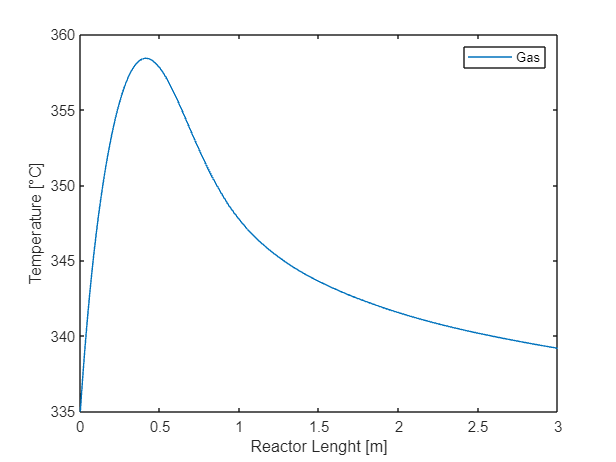

figure(1)
plot(t,y(:,7)-273.15)
xlabel('Reactor Lenght [m]')
ylabel('Temperature [°C]')
legend('Gas')

There are 2 new questions about the plot above: Why we have a peak in this plot? Why the temperature has been fallen off?

Initially, the heat removal of the system is low, which leads to raise reactor temperature. Then, with passing the reactor length, the molten salts are decreasing the internal heat of reactor and prevent from raising temperature (temperature runaway). 

The psuodo homogeneous approach assumes that all parts have same temperature and there isn't any external gradient between catalyst surface and gas, and also between catalyst surface and pores. 

The assumptions of model will create limitations in physical results in any mode of simulation. 

- The pressure have effect on number of tubes. Less pressure => High number of tubes => Less Temperature Profile

- High Inlet Pressure => High Density => Low velocity => Low Pressure Drop

- The reaction depends on pressure square ($p^2$)

## Jalal's Notes

As mentioned in the question we want to produce PA from the oxidation of o-xylene in a catalytic bed reactor. As requested by the question I use the 1D pseudo-homogeneous model with the heat transfer computed through the Dixon-Specchia correlation. This model based on the assumption that concentration and temperature gradients only occur in the axial direction and the only transport mechanism in this direction of flow itself. To get the number of tubes needed for this question, we could calculate the productivity for one tube and with the goal that we want from this unit which is 8000 ton/year we could get the total number of tubes needed. To get the productivity of tube we need to know conversion, selectivity and yield in the reactor. Also, there is a limit on the system that the maximum pressure drop per meter is not be more than 0.1 bar/m. So, to get these values we need to have the concentration, Temperature and pressure gradients, and for that we could write a mass, energy, and mechanical energy balance on the system, and get these equations. According to the equations that we have and the data which are given we could modify them and write them based on G=4900 kg/h/m2. We also need to get the values for their boundary condition. We know that at z=0 T=T0=335 C, P=P0=P_ outlet + delta P=1.3 bar, and for mass fraction in the inlet we need to calculate it. First, we need to identify the species which are 6. Then, according to question we are diluting the o-x with air so the inlet moles are only N2, O-X, and O2 [0.79 0.013 0.21 0 0 0]. With having these moles, we could calculate the molar fraction. Now with multiplying them with their molecular weight we could get the mass of every species and at the end calculate the inlet mass fraction. Now, according to the equation we could calculate void fraction, surface per unit volume, and overall heat transfer coefficients. To get the gas density, because we have an ideal gas mixture we could use ideal gas rule, and get the molar gas density. with multiplying it with 10^-3 and mw, we turn it to mass gas density. To get the superficial velocity, we need to do this: G/mass gas density/3600 and get v with the unit of m/s. Now, we need to find the stochiometric coefficients and modify the reaction rate. Stochiometric coefficients are achievable from the three reaction scheme that we have. The reaction rate should be written in terms of total pressure(bar) and mol fraction of species in the reactor. Now, we only have three equations and three unknowns and could get the change in mass fraction of any species in the reactor, the thermal profile, the conversion, selectivity and yield. The parameters that we could change to reduce the number of tubes are inlet pressure and temperature, flow rate, o-x concentration, and external temperature. With increasing the pressure, the gas density and reaction rate increases. This will enhance the productivity and reduce the number of tubes. But it cannot reduce it under 9000 tubes, because the reaction rate which is exothermic is increasing in the reactor, and as we only have one hot spot, the thermal run away happen and the reactor design collapse. The same thing happens when we increase the other parameters. The best procedure is to dilute the catalytic bed and divide it into two sections according to the first hot spot that we have making two hot spots in the reactor. The first section should be diluted to decrease the reaction happening their and the second one only have the catalyst to make the reaction increase and make the second hot spot. Now we could easily increase the pressure or o-x concentration without reaching thermal runway and exceed the limit of the previous design.